# **Controls for parameter tuning**

Linear classification

Holdout 50 or 80% --> community uses 80%

 --> maybe check a few cells

============

OBSERVATIONS

============

Analysis on MODULATION

==> WHAT ABOUT PEAK MAGNITUDE

==> WHAT NOT JUST THE PEAKS (full signal)

-  Encoder

-  EyeCam_Wheel --> check against encoder

-  L Forelimb

-  R Forelimb

-  Trunk (highest for 3-4 cells, so keep for now)

-  BodyCam LWhisker : The good one (behind, on black background)

- BodyCam RWhisker (on the whiskerpad, from the front + cuetip)

- Perioral

- trigger

- F0

**  shuffles (temporal and spatial permutation, separately, for all Conditions)

Excluded : 

- Laser

- BodyCam Eye --> meh

- Eycam whiskerpad (just check 09-12 exp 9-11 exp2 04-30-exp4

- eyecam Eye (check 09-04 exp2)

- NOT RT3D_MC BUT BASELINE F0 instead

============

PREDICTORS

============

* All ROIs

* Highest PHATE (+ and - for PHATEs 1-3)

* Perisomatic ROIS (6)

* 6 random ROIs 

* High PHATES GROUPS (6 ROIs of the PHATES 1->3 + and -)

# 1. Load experiment

% note : the experiment loaded here has been preprocessed for peak detection and
% rescaling. If this is not the case, you need to do it.
%load('C:\Users\THE BEASTWO\Documents\MATLAB\arboreal_scans_final_new_zscored_compressed\2019-11-05_exp_3\2019-11-05_exp_3.mat')
%load('C:\Users\THE BEASTWO\Documents\MATLAB\arboreal_scans_final_new_zscored_compressed\2019-10-31_exp_1\2019-10-31_exp_1.mat')
load('C:\Users\Antoine.Valera\MATLAB\newextraction_dF_F0_zscored\2019-10-01_exp_1\2019-10-01_exp_1.mat')

# 2. Define the Analysis Settings

## Arboreal Scan settings

obj.detrend     = 0;% -1; %'auto'


	Correlation done by group median, using your current binning, 
	Reference trace is the somatic signal average, at the indicated timpoints. 
	Correlation computed using data at peak time only, 


obj.filter_win  = -1; % 
obj.rendering   = 0;
obj.process({'distance',50}); % will use obj.filter_win and obj.rendering
obj.get_dimensionality([],'phate','peaks_subtracted',[]);
obj.cluster_factors('dbscan',-5)


	Correlation done by group median, using your current binning, 
	Reference trace is the somatic signal average, at the indicated timpoints. 
	Correlation computed using data at peak time only, 

	Correlation done by group median, using your current binning, 
	Reference trace is the somatic signal average, at the indicated timpoints. 
	Correlation computed using data at peak time only, 


## Machine Learning settings

total dendritic length (-excluded branches) : 4254 um
total dendritic length (-excluded branches) : 3248 um
total dendritic length (-excluded branches) : 4254 um
total dendritic length (-excluded branches) : 3248 um
total dendritic length (-excluded branches) : 4254 um
total dendritic length (-excluded branches) : 3248 um
total dendritic length (-excluded branches) : 4254 um
total dendritic length (-excluded branches) : 3248 um
total dendritic length (-excluded branches) : 4254 um
total dendritic length (-excluded branches) : 3248 um
total dendritic length (-excluded branches) : 4254 um
total dendritic length (-excluded branches) : 3248 um
total dendritic length (-excluded branches) : 4254 um
total dendritic length (-excluded branches) : 3248 um
total dendritic length (-excluded branches) : 4254 um
total dendritic length (-excluded branches) : 3248 um
total dendritic length (-excluded branches) : 4254 um


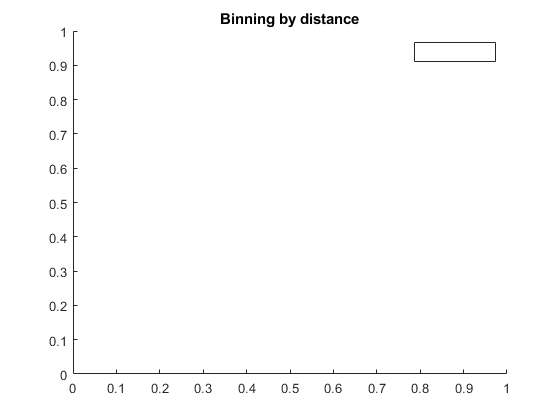

Now detecting events with global pairwise correlation at least > 0.2 % 
    * Events detection is using PAIRWISE CORRELATION between all provided traces 
      Epochs of correlated changes of activity across a set % of the tree/pop will be considered as an event 


THR_FOR_GLOBAL = 0.5000

    * Events occuring in > 50% of the tree are considered global 
    * Maximal tree correlation is 82.7139%. A values < 100% indicates that either some sections belong to other neurons, or that the entire tree is never fully coactivated
      This function cannot distinguish between these two cases, but the value (max_corr_before_norm) will be set as the maximal possible correlation, and the globality index is proportional to this. This assumes that the entire tree CAN be correlated 
    * 312 events have been detected 
    * Peak times were extracted on the scaled avrage of all traces, but using the event times obtained with the global pairwise correlation. A jitter of 66.6667 ms was tolerated around the correated peak time 
    * 0events were of large enough amplitude to be detected on the averaged traces, but were not corrlated across the entire tree 


THR_FOR_CONNECTION = 0.2000

* Now detecting ROIs that are either,
      - so poorly correlated to the rest of the tree that they probably belong to another cell (or have no signal).
      - are member of batch_params.excluded_branches 
* Threshold for exclusion is  0.2 % 


RECOVERY_THR = 0.8000

ans = 15660×1 single column vector
   11.5640
    9.9140
    8.2271
    6.7825
    7.3537
    5.9792
    4.8149
    3.5854
    3.1047
    2.3662


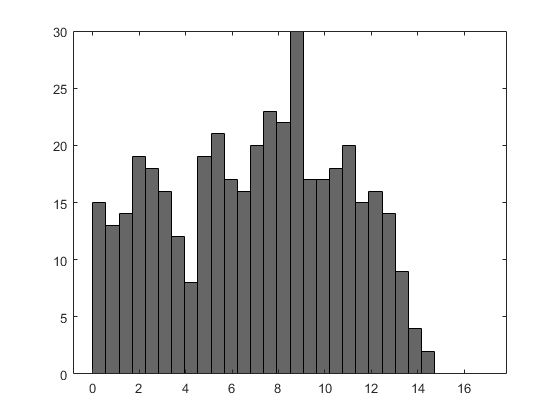

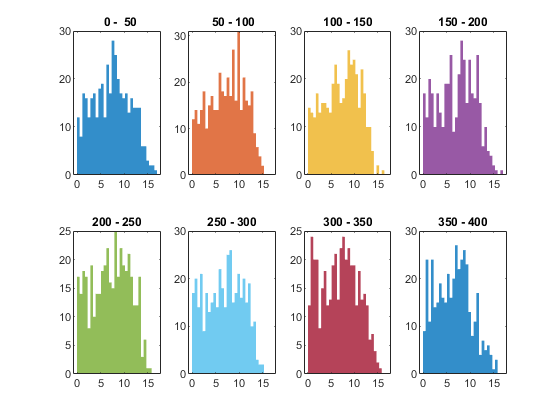

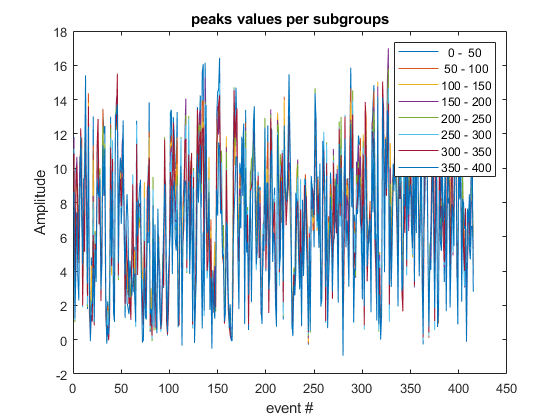

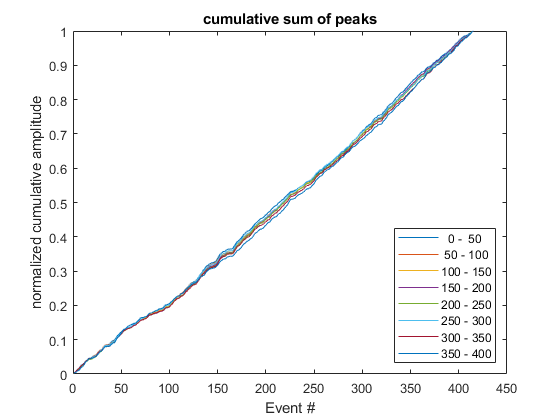

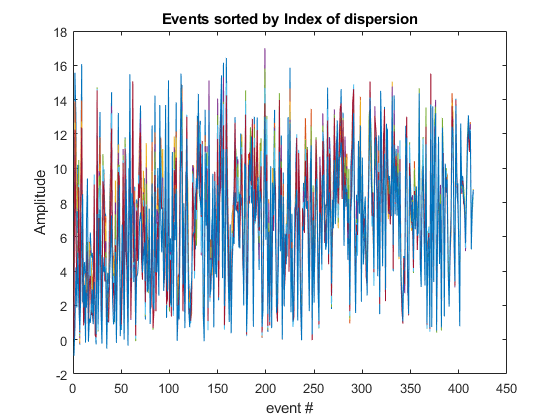

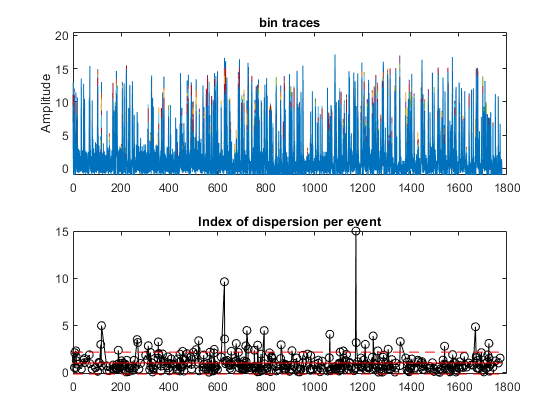

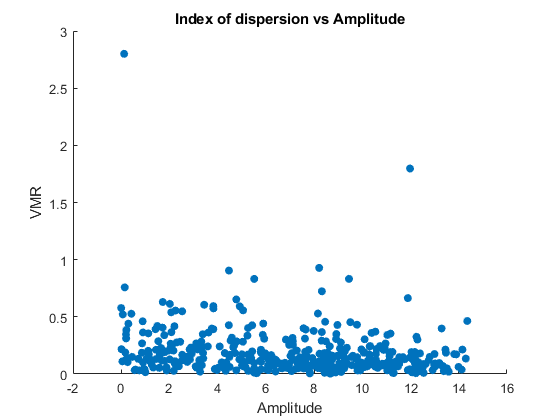

ans = 415×1 single column vector
    0.5142
    2.0978
    2.2969
    0.5354
    1.6583
    1.2512
    0.8654
    0.3745
    1.3077
    1.4799


Using current obj.cc_mode
Using current obj.cc_mode : groups_peaks


Doing PCA
PCA using random SVD
PCA took 0.016161 seconds
using alpha decaying kernel
Computing alpha decay kernel:
Number of samples = 168
First iteration: k = 100
Number of samples below the threshold from 1st iter: 168
   Symmetrize affinities
   Done computing kernel
Computing kernel took 0.22571 seconds
Make kernel row stochastic
Running PHATE without landmarking
Finding optimal t using VNE
VNE optimal t = 30


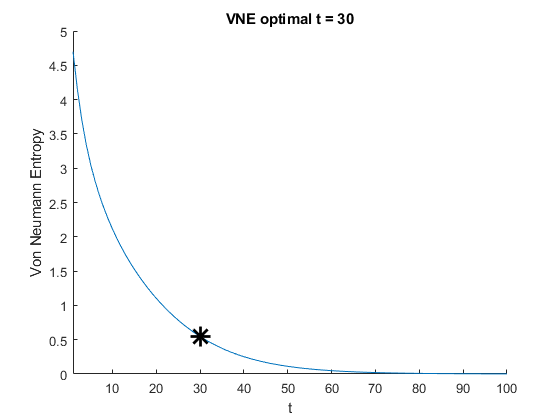

Diffusing operator
Diffusion took 0.0032898 seconds
Computing potential distances
using -log(P) potential distance
Computing potential distance took 0.010713 seconds
Doing classical MDS
CMDS took 0.0043141 seconds
Doing metric MDS:

                     Stress          Norm of         Norm of     Line Search
   Iteration       Criterion        Gradient           Step       Iterations
  ---------------------------------------------------------------------------
           0        0.946775       0.0154798
           1        0.324305      0.00823909         24.4531              10
           2        0.270834      0.00844927         10.7984               9
           3        0.188612       0.0126612         15.7161              12
           4        0.114415       0.0120088         6.75372              10
           5       0.0720121       0.0095585          4.4443               9
           6       0.0478971      0.00968998         2.67647              10
           7       0.0342314

method = 'dbscan'

rendering = logical
   0


MIN_CLUSTER_SIZE = 4

testing epsilon = 0.1
testing epsilon = 0.10475
testing epsilon = 0.10972
testing epsilon = 0.11492
testing epsilon = 0.12038
testing epsilon = 0.12609
testing epsilon = 0.13207
testing epsilon = 0.13834
testing epsilon = 0.1449
testing epsilon = 0.15178
testing epsilon = 0.15898
testing epsilon = 0.16652
testing epsilon = 0.17443
testing epsilon = 0.1827
testing epsilon = 0.19137
testing epsilon = 0.20045
testing epsilon = 0.20997
testing epsilon = 0.21993
testing epsilon = 0.23036
testing epsilon = 0.2413
testing epsilon = 0.25275
testing epsilon = 0.26474
testing epsilon = 0.2773
testing epsilon = 0.29046
testing epsilon = 0.30424
testing epsilon = 0.31868
testing epsilon = 0.3338
testing epsilon = 0.34964
testing epsilon = 0.36623
testing epsilon = 0.38361
testing epsilon = 0.40182
testing epsilon = 0.42088
testing epsilon = 0.44085
testing epsilon = 0.46177
testing epsilon = 0.48369
testing epsilon = 0.50664
testing epsilon = 0.53068
testing epsilon = 0.55586
testing epsilon = 0.5

MIN_GP = 4

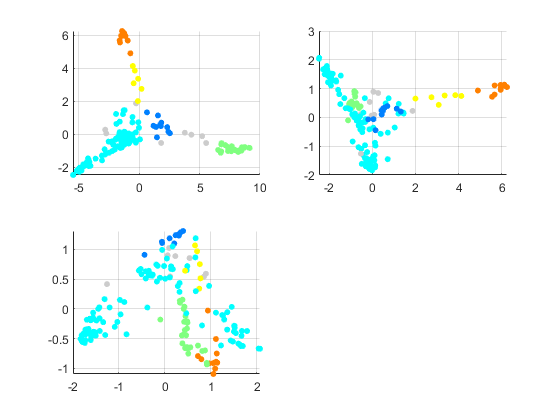

obj = Using current obj.cc_mode : groups_peaks
  arboreal_scan_experiment with properties:

         extraction_method: 'median'
             source_folder: 'C:/Users/Antoine.Valera/MATLAB/newextraction_dF_F0_zscored/2019-10-01_exp_1/'
             update_folder: ''
      extracted_data_paths: {1×30 cell}
               need_update: [1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1]
            arboreal_scans: {1×30 cell}
                 timescale: [1×1 struct]
                      demo: 0
        auto_save_analysis: 1
         auto_save_figures: 0
                filter_win: [0 0]
               filter_type: 'gaussian'
              dim_red_type: 'pca'
                  peak_thr: 2
               bad_ROI_thr: 0.2000
                   cc_mode: 'groups_peaks'
                   detrend: 0
              is_detrended: 1
               is_rescaled: 1
            default_handle: @(x)load_several_e

total dendritic length (-excluded branches) : 4254 um
total dendritic length (-excluded branches) : 4254 um
total dendritic length (-excluded branches) : 4254 um
total dendritic length (-excluded branches) : 4254 um
total dendritic length (-excluded branches) : 4254 um
total dendritic length (-excluded branches) : 4254 um
total dendritic length (-excluded branches) : 4254 um
total dendritic length (-excluded branches) : 4254 um
total dendritic length (-excluded branches) : 4254 um
total dendritic length (-excluded branches) : 4254 um
total dendritic length (-excluded branches) : 4254 um
total dendritic length (-excluded branches) : 4254 um
total dendritic length (-excluded branches) : 4254 um
total dendritic length (-excluded branches) : 4254 um
total dendritic length (-excluded branches) : 4254 um
total dendritic length (-excluded branches) : 4254 um
total dendritic length (-excluded branches) : 4254 um
total dendritic length (-excluded branches) : 4254 um
total dendritic length (-exc

use_classifier  = false;                % true or false
method          = 'linear';             % 'linear' or 'svm'    

Doing PCA
PCA using random SVD
PCA took 0.0051681 seconds
using alpha decaying kernel
Computing alpha decay kernel:
Number of samples = 168
First iteration: k = 100
Number of samples below the threshold from 1st iter: 168
   Symmetrize affinities
   Done computing kernel
Computing kernel took 0.01365 seconds
Make kernel row stochastic
Running PHATE without landmarking
Finding optimal t using VNE
VNE optimal t = 30


Diffusing operator
Diffusion took 0.0033157 seconds
Computing potential distances
using -log(P) potential distance
Computing potential distance took 0.0031179 seconds
Doing classical MDS
CMDS took 0.0021701 seconds
Doing metric MDS:

                     Stress          Norm of         Norm of     Line Search
   Iteration       Criterion        Gradient           Step       Iterations
  ---------------------------------------------------------------------------
           0        0.946775       0.0154797
           1        0.324313      0.00824018         24.4545              10
           2        0.270835      0.00845015         10.7995               9
           3        0.188641       0.0126599          15.709              12
           4        0.114394       0.0120066         6.75734              10
           5       0.0720107      0.00955855         4.44251               9
           6       0.0478966      0.00968953         2.67707              10
           7       0.034231

variable_type   = 'peaks_subtracted';   % 'peak_subtracted' or any other set of conditions / timepoints

behaviours      = {'encoder','EyeCam_L_forelimb','EyeCam_R_forelimb','BodyCam_L_whisker','BodyCam_R_whisker','EyeCam_Perioral','trigger','baseline'};
%behaviours      = {'encoder','BodyCam_L_whisker'}; 
N_iter          = 10;                   % N iterations
KFold           = 5; 
holdout         = 0;                    % percentage of data held out for final testing. If 0, we use KFoldLoss with custom Pearson coeff to estimate the score
rendering       = 1;                    % If 0 no figure, if 1 summary plot is display per iteraton + averages, if 2, individual iteration data is displayed , if 3 hyperparameter optimization plot are displayed.

# 3. Regular Behaviour Prediction

## On all ROIs

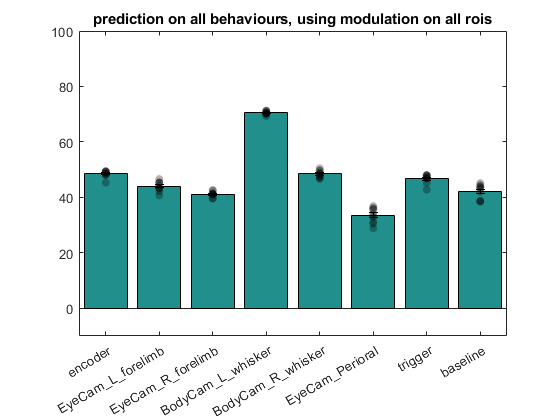

ROI_selection       = [];
result_linear       = predict_behaviours(obj,use_classifier ,... % true or false
                                             method         ,... % 'linear' or 'svm'
                                             variable_type  ,... % 'peak_subtracted' or any other set of conditions / timepoints
                                             behaviours     ,... % Cell array of behaviours. add "_shuffled" to a behaviours name to shuffle timepoints
                                             ROI_selection  ,... % Cell array of ROI to use as predictor. One cell = one predictor. When multiple value per cell, values are avergaed. If passing a list, then all ROIs are used individually
                                             N_iter         ,... % N iterations
                                             false          ,... % if true, random groups are generated matching "ROI_selection" size
                                             'optimize_hyper', true     ,... % ML varargin ; if true, Lambda is optimized for each iteration
                                             'rendering', rendering     ,... % If 0 no figure, if 1 summary plot is display per iteraton + averages, if 2, individual iteration data is displayed , if 3 hyperparameter optimization plot are displayed.
                                             'optimization_method', 'manual',... % "manual" or "native". Native uses MATLAB baysian search parameter optimization for Lambda. Native generate a search grid and find Lambda with the best prediction score.. 
                                             'holdout', holdout         ,... % percentage of data held out for final testing. If 0, we use KFoldLoss with custom Pearson coeff to estimate the score
                                             'kfold', KFold             ,...
                                             'title', 'Prediction on all behaviours, using modulation on all ROIs'); % Bar chart title

## On ROIs with High Phate magnitude (0-lag)

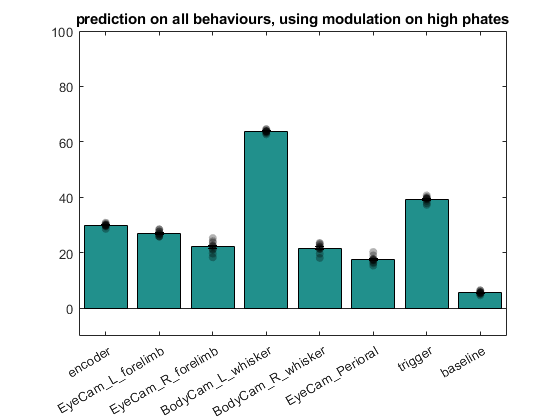

N_phates        = 3;    % N dimensions
cutoff          = 0;    % 0 is just min and max
bidirectional   = true; % Postive AND negative magnitudes

try
    groups = get_high_phate_ROIs(obj, N_phates, cutoff, bidirectional);
catch
    obj.get_dimensionality([],'phate','peaks_subtracted',[]);
    groups = get_high_phate_ROIs(obj, N_phates, cutoff, bidirectional);
end

% To study phates 1-3 up/down together and avg'd across ROIs (e.g. contents of cell array are avg'd prior to running ML) 
% e.g. if the cell 'cares' about avg. signals coming out of larger than our ROIs compartments
ROI_selection       = groups;
result_linear       = predict_behaviours(obj,use_classifier ,... % true or false
                                             method         ,... % 'linear' or 'svm'
                                             variable_type  ,... % 'peak_subtracted' or any other set of conditions / timepoints
                                             behaviours     ,... % Cell array of behaviours. add "_shuffled" to a behaviours name to shuffle timepoints
                                             ROI_selection  ,... % Cell array of ROI to use as predictor. One cell = one predictor. When multiple value per cell, values are avergaed. If passing a list, then all ROIs are used individually
                                             N_iter         ,... % N iterations
                                             false          ,... % if true, random groups are generated matching "ROI_selection" size
                                             'optimize_hyper', true     ,... % ML varargin ; if true, Lambda is optimized for each iteration
                                             'rendering', rendering     ,... % If 0 no figure, if 1 summary plot is display per iteraton + averages, if 2, individual iteration data is displayed , if 3 hyperparameter optimization plot are displayed.
                                             'optimization_method', 'manual',... % "manual" or "native". Native uses MATLAB baysian search parameter optimization for Lambda. Native generate a search grid and find Lambda with the best prediction score.. 
                                             'holdout', holdout         ,... % percentage of data held out for final testing. If 0, we use KFoldLoss with custom Pearson coeff to estimate the score
                                             'kfold', KFold             ,...
                                             'title', 'Prediction on all behaviours, using modulation on High Phates'); % Bar chart title

## On individual ROI groups identified by individual Phates (0-lag)

ans =     12    14


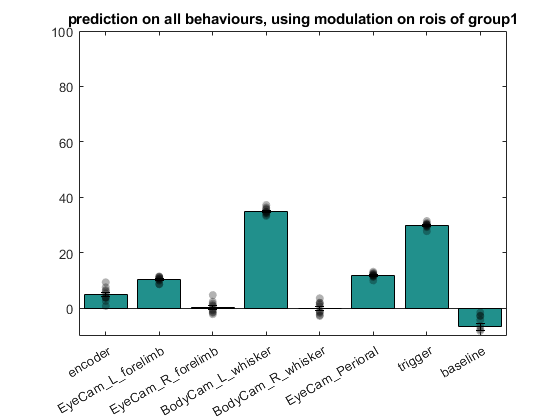

ans =     77   107


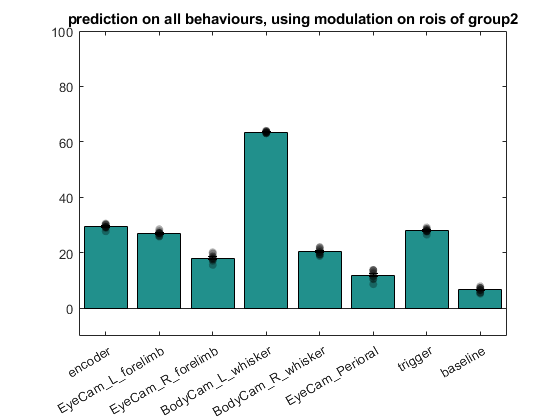

ans =     65    69    71    89


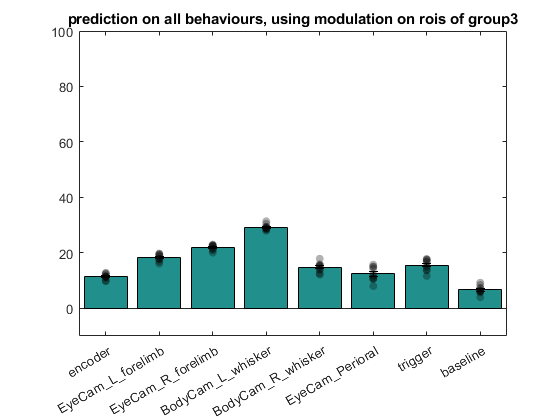

ans =     77   107


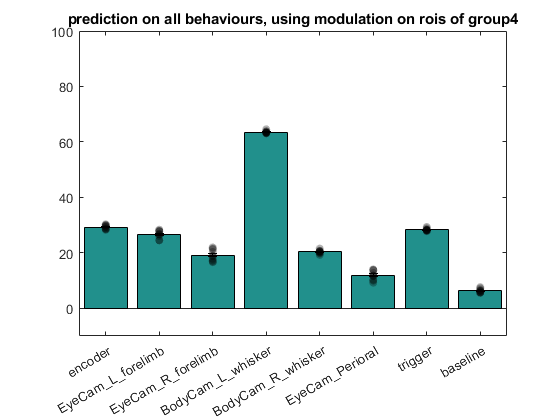

ans =     77   107


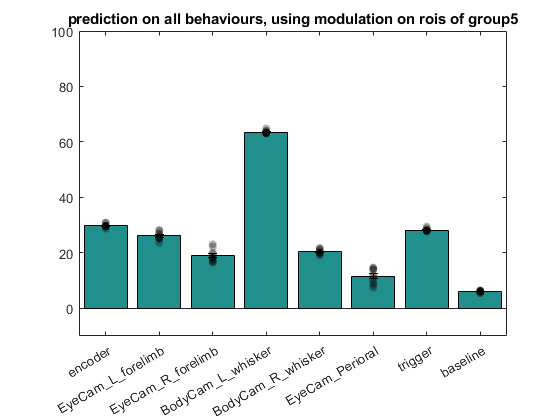

ans =    126   127   132   133   136   148   150


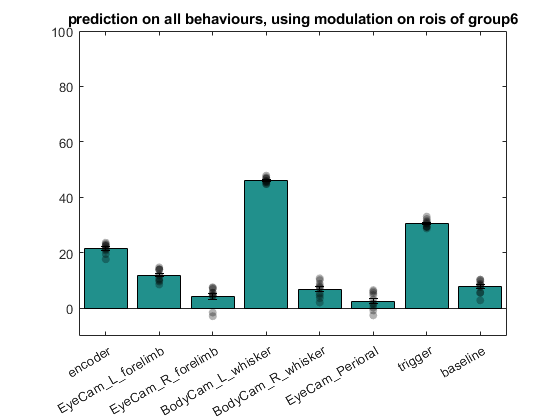

ans =      2    48    83


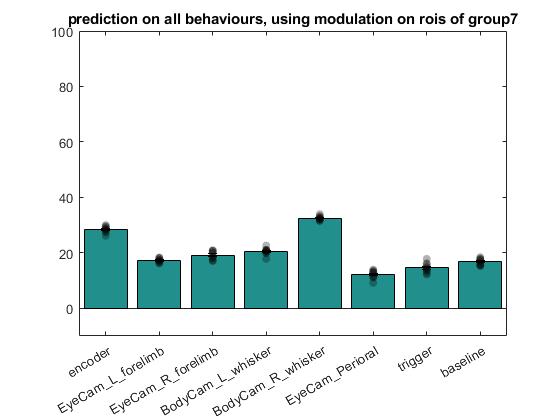

ans = 69

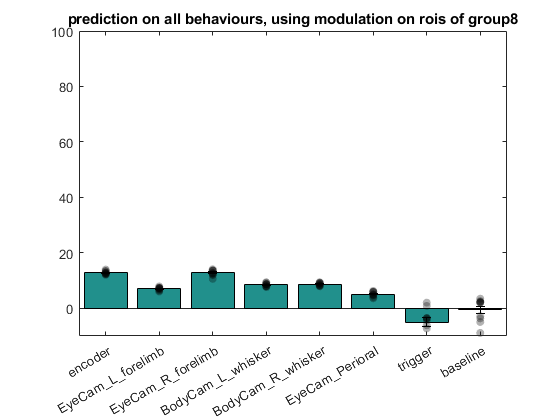

ans = 101

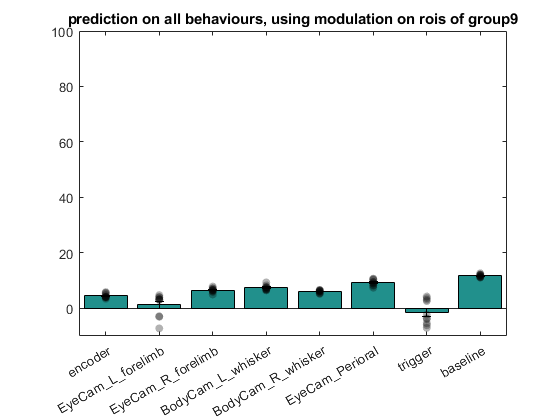

ans =     40    43


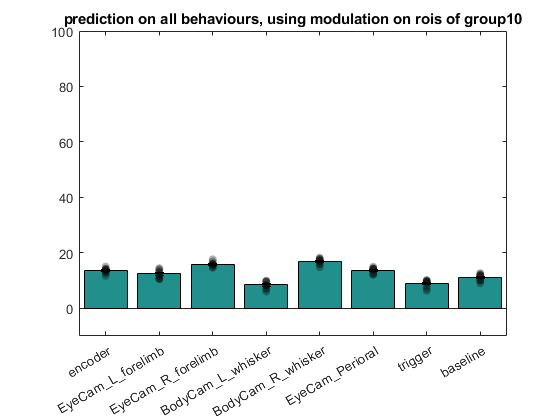

ans = 1

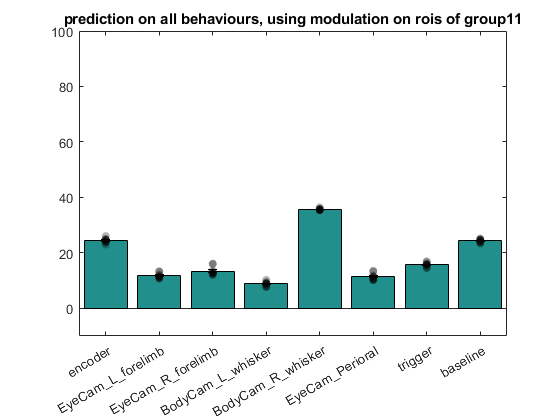

ans =      8    67


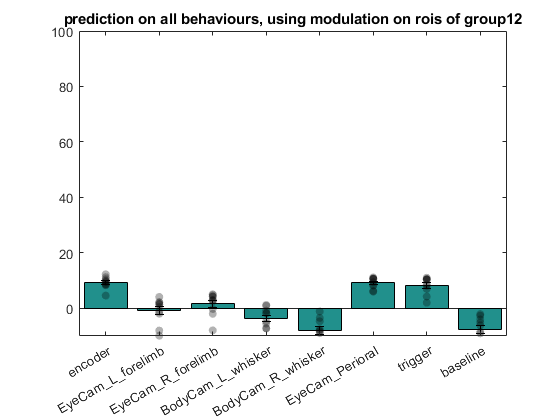

ans =     12    14


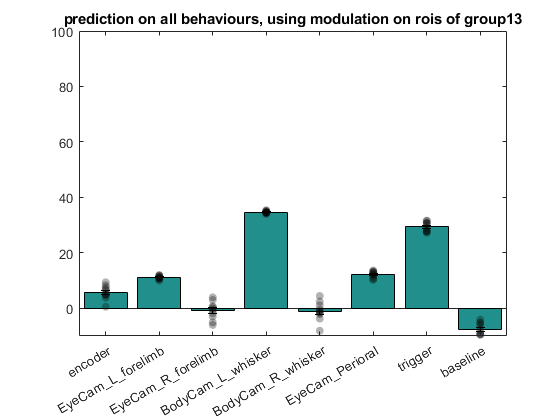

ans =     29    32


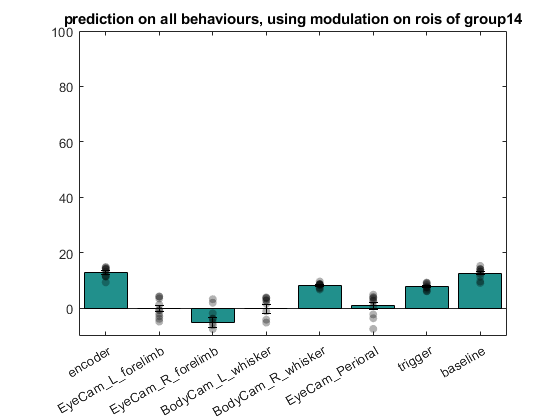

ans = 16

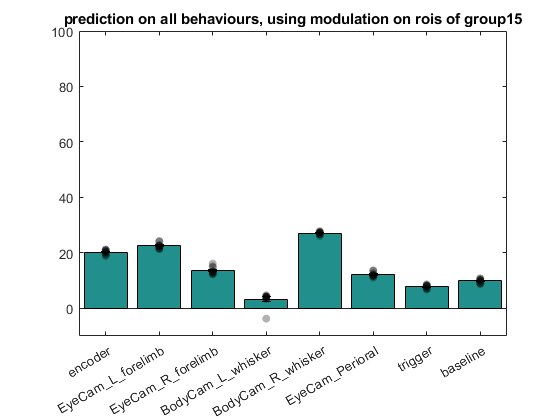

ans = 34

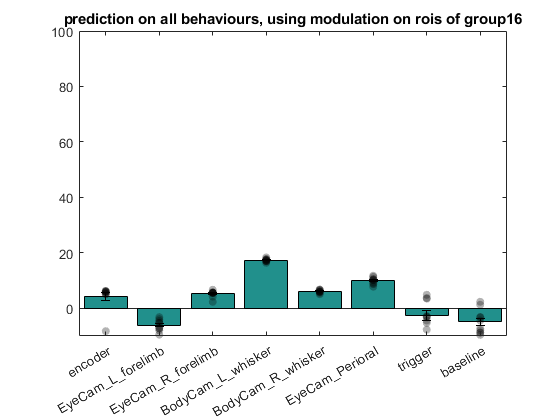

ans = 28

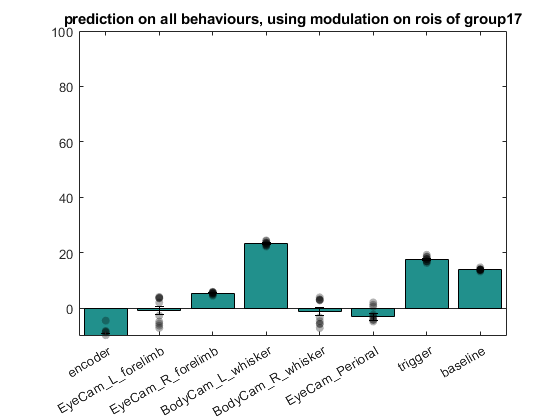

ans = 108

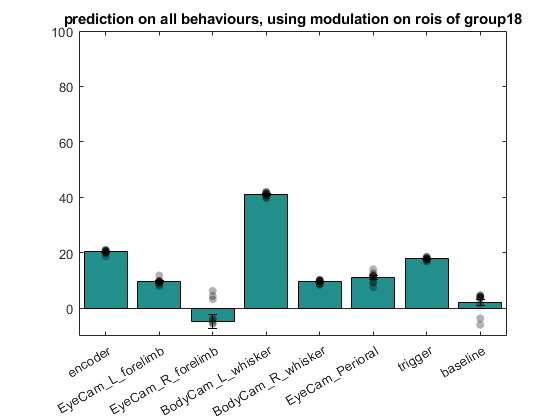

% to study phate 1,2 or 3 up or down in isolation (e.g. phate 1 up only) or clusters (e.g. DBSCAN)
% need to know what is in groups for this to be interpretable
N_phates        = 9;    % N dimensions
cutoff          = 2;    % 0 is just min and max
bidirectional   = true; % Postive AND negative magnitudes
groups          = get_high_phate_ROIs(obj, N_phates, cutoff, bidirectional);
extracted_beh   = prepare_behaviour_data(obj, behaviours);
ind_phate_res   = {};

for jj = 1:numel(groups)
    groups{jj}
    [~,~,~, ind_phate_res{jj}]   = predict_behaviours(obj,use_classifier ,... % true or false
                                                         method         ,... % 'linear' or 'svm'
                                                         variable_type  ,... % 'peak_subtracted' or any other set of conditions / timepoints
                                                         extracted_beh  ,... % Cell array of behaviours. add "_shuffled" to a behaviours name to shuffle timepoints
                                                         groups{jj}     ,... % Cell array of ROI to use as predictor. One cell = one predictor. When multiple value per cell, values are avergaed. If passing a list, then all ROIs are used individually
                                                         N_iter         ,... % N iterations
                                                         false          ,... % if true, random groups are generated matching "ROI_selection" size
                                                         'optimize_hyper', true     ,... % ML varargin ; if true, Lambda is optimized for each iteration
                                                         'rendering', true     ,... % If 0 no figure, if 1 summary plot is display per iteraton + averages, if 2, individual iteration data is displayed , if 3 hyperparameter optimization plot are displayed.
                                                         'optimization_method', 'manual',... % "manual" or "native". Native uses MATLAB baysian search parameter optimization for Lambda. Native generate a search grid and find Lambda with the best prediction score.. 
                                                         'holdout', holdout         ,... % percentage of data held out for final testing. If 0, we use KFoldLoss with custom Pearson coeff to estimate the score
                                                         'kfold', KFold             ,...
                                                         'title', ['Prediction on all behaviours, using modulation on ROIs of group', num2str(jj)]); % Bar chart title
end


figure();subplot(1,2,1);
a = cell2mat(ind_phate_res)';%a(a < 20) = 0;
imagesc(a ./ max(a));caxis([0,1]);colormap(gray);cb = colorbar;cb.Label.String = {'Normalized predictive score ','(normed to max predictibility per behaviour)'}

cb =   ColorBar (Normalized predictive score , (normed to max predictibility per behaviour)) with properties:

    Location: 'eastoutside'
      Limits: [0 1]
    FontSize: 7.6500
    Position: [0.3832 0.1095 0.0239 0.8143]
       Units: 'normalized'

  Show all properties


xticks(1:numel(behaviours));xticklabels(cellfun(@(x) strrep(x,'_',' '), behaviours, 'uni', false));xtickangle(45); hold on; xlabel('Behaviour');
yticks(1:2:18);hold on;yticklabels(cellfun(@(x) num2str(x), num2cell(1:N_phates), 'uni', false)); ylabel('Phate #');

subplot(1,2,2);a = cell2mat(ind_phate_res)';%a(a < 20) = 0;
imagesc(a ./ max(a, [],2));caxis([0,1]);colormap(gray);cb = colorbar;cb.Label.String = {'Normalized predictive score ','(normed to max predictibility in phate)'}

cb =   ColorBar (Normalized predictive score , (normed to max predictibility in phate)) with properties:

    Location: 'eastoutside'
      Limits: [0 1]
    FontSize: 7.6500
    Position: [0.8242 0.1095 0.0241 0.8143]
       Units: 'normalized'

  Show all properties


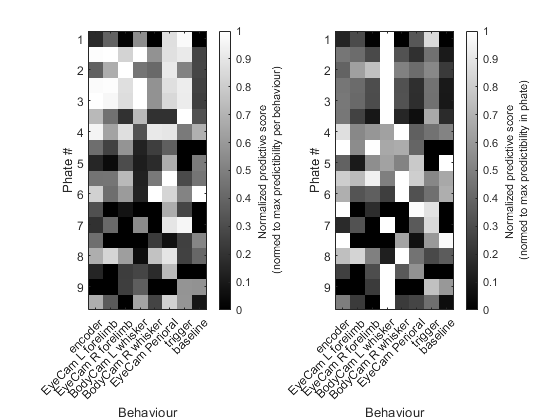

xticks(1:numel(behaviours));xticklabels(cellfun(@(x) strrep(x,'_',' '), behaviours, 'uni', false));xtickangle(45); hold on; xlabel('Behaviour');
yticks(1:2:18);hold on;yticklabels(cellfun(@(x) num2str(x), num2cell(1:N_phates), 'uni', false)); ylabel('Phate #');

## On ROIs identified by clustering

method = 'dbscan'

rendering = logical
   0


MIN_CLUSTER_SIZE = 4

testing epsilon = 0.1
testing epsilon = 0.10475
testing epsilon = 0.10972
testing epsilon = 0.11492
testing epsilon = 0.12038
testing epsilon = 0.12609
testing epsilon = 0.13207
testing epsilon = 0.13834
testing epsilon = 0.1449
testing epsilon = 0.15178
testing epsilon = 0.15898
testing epsilon = 0.16652
testing epsilon = 0.17443
testing epsilon = 0.1827
testing epsilon = 0.19137
testing epsilon = 0.20045
testing epsilon = 0.20997
testing epsilon = 0.21993
testing epsilon = 0.23036
testing epsilon = 0.2413
testing epsilon = 0.25275
testing epsilon = 0.26474
testing epsilon = 0.2773
testing epsilon = 0.29046
testing epsilon = 0.30424
testing epsilon = 0.31868
testing epsilon = 0.3338
testing epsilon = 0.34964
testing epsilon = 0.36623
testing epsilon = 0.38361
testing epsilon = 0.40182
testing epsilon = 0.42088
testing epsilon = 0.44085
testing epsilon = 0.46177
testing epsilon = 0.48369
testing epsilon = 0.50664
testing epsilon = 0.53068
testing epsilon = 0.55586
testing epsilon = 0.5

MIN_GP = 4

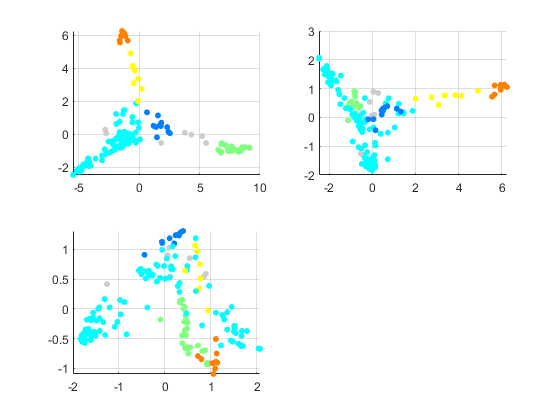

obj.cluster_factors('dbscan',-5);

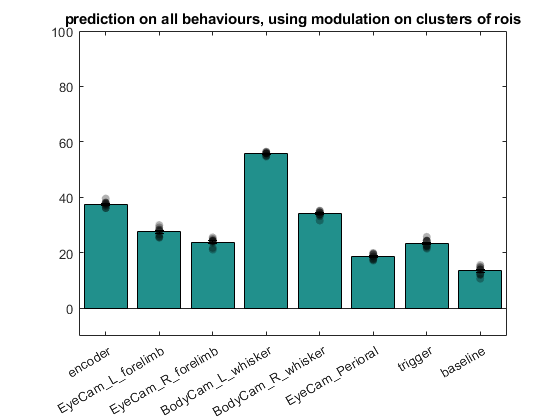

ROI_selection       = obj.dimensionality.clust_groups; 

result_linear       = predict_behaviours(obj,use_classifier ,... % true or false
                                             method         ,... % 'linear' or 'svm'
                                             variable_type  ,... % 'peak_subtracted' or any other set of conditions / timepoints
                                             behaviours     ,... % Cell array of behaviours. add "_shuffled" to a behaviours name to shuffle timepoints
                                             ROI_selection  ,... % Cell array of ROI to use as predictor. One cell = one predictor. When multiple value per cell, values are avergaed. If passing a list, then all ROIs are used individually
                                             N_iter         ,... % N iterations
                                             false          ,... % if true, random groups are generated matching "ROI_selection" size
                                             'optimize_hyper', true     ,... % ML varargin ; if true, Lambda is optimized for each iteration
                                             'rendering', rendering     ,... % If 0 no figure, if 1 summary plot is display per iteraton + averages, if 2, individual iteration data is displayed , if 3 hyperparameter optimization plot are displayed.
                                             'optimization_method', 'manual',... % "manual" or "native". Native uses MATLAB baysian search parameter optimization for Lambda. Native generate a search grid and find Lambda with the best prediction score.. 
                                             'holdout', holdout         ,... % percentage of data held out for final testing. If 0, we use KFoldLoss with custom Pearson coeff to estimate the score
                                             'kfold', KFold             ,...
                                             'title', 'Prediction on all behaviours, using modulation on clusters of ROIs'); % Bar chart title

## On individual ROI groups following clustering

ans =      5
    30
    36
    37
    38
    39
    40
    41
    42
    43


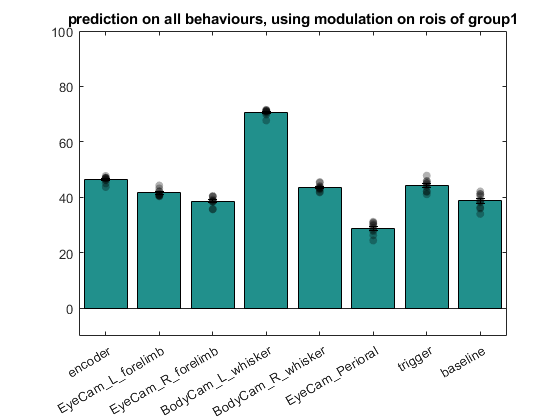

ans =      6
     7
     9
    10
    11
    12
    13
    14
    15
    17


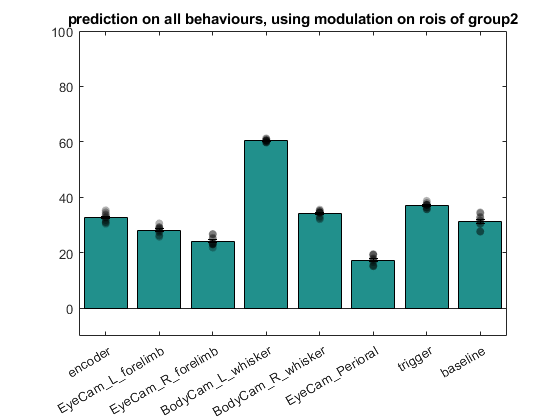

ans =      1
     2
    47
    48
    49
    80
    82
    83
    84
    93


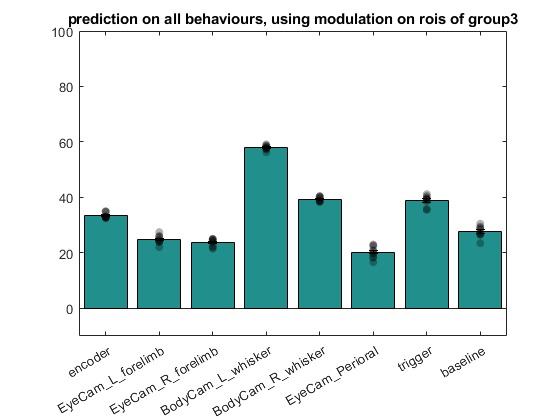

ans =     63
    64
    65
    67
    68
    69
    70
    71
    87
    88


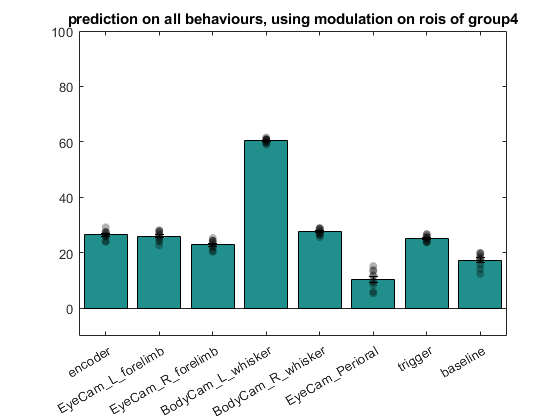

ans =     53
    54
    55
    56
    60
    61
    62


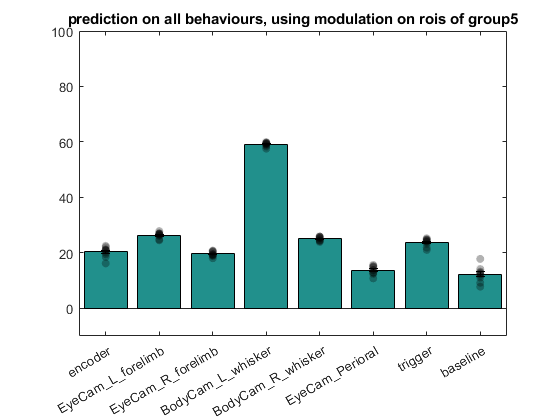

groups          = obj.dimensionality.clust_groups; 
extracted_beh   = prepare_behaviour_data(obj, behaviours);
ind_clust_res   = {};

for jj = 1:numel(groups)
    groups{jj}
    [~,~,~, ind_clust_res{jj}]   = predict_behaviours(obj,use_classifier ,... % true or false
                                                         method         ,... % 'linear' or 'svm'
                                                         variable_type  ,... % 'peak_subtracted' or any other set of conditions / timepoints
                                                         extracted_beh  ,... % Cell array of behaviours. add "_shuffled" to a behaviours name to shuffle timepoints
                                                         groups{jj}     ,... % Cell array of ROI to use as predictor. One cell = one predictor. When multiple value per cell, values are avergaed. If passing a list, then all ROIs are used individually
                                                         N_iter         ,... % N iterations
                                                         false          ,... % if true, random groups are generated matching "ROI_selection" size
                                                         'optimize_hyper', true     ,... % ML varargin ; if true, Lambda is optimized for each iteration
                                                         'rendering', true     ,... % If 0 no figure, if 1 summary plot is display per iteraton + averages, if 2, individual iteration data is displayed , if 3 hyperparameter optimization plot are displayed.
                                                         'optimization_method', 'manual',... % "manual" or "native". Native uses MATLAB baysian search parameter optimization for Lambda. Native generate a search grid and find Lambda with the best prediction score.. 
                                                         'holdout', holdout         ,... % percentage of data held out for final testing. If 0, we use KFoldLoss with custom Pearson coeff to estimate the score
                                                         'kfold', KFold             ,...
                                                         'title', ['Prediction on all behaviours, using modulation on ROIs of group', num2str(jj)]); % Bar chart title
end


figure();subplot(1,2,1);
a = cell2mat(ind_clust_res)';%a(a < 20) = 0;
imagesc(a ./ max(a));caxis([0,1]);colormap(gray);cb = colorbar;cb.Label.String = {'Normalized predictive score ','(normed to max predictibility per behaviour)'}

cb =   ColorBar (Normalized predictive score , (normed to max predictibility per behaviour)) with properties:

    Location: 'eastoutside'
      Limits: [0 1]
    FontSize: 7.6500
    Position: [0.3832 0.1095 0.0239 0.8143]
       Units: 'normalized'

  Show all properties


xticks(1:numel(behaviours));xticklabels(cellfun(@(x) strrep(x,'_',' '), behaviours, 'uni', false));xtickangle(45); hold on; xlabel('Behaviour');
yticks(1:2:18);hold on;yticklabels(cellfun(@(x) num2str(x), num2cell(1:N_phates), 'uni', false)); ylabel('Phate #');

subplot(1,2,2);a = cell2mat(ind_clust_res)';%a(a < 20) = 0;
imagesc(a ./ max(a, [],2));caxis([0,1]);colormap(gray);cb = colorbar;cb.Label.String = {'Normalized predictive score ','(normed to max predictibility in phate)'}

cb =   ColorBar (Normalized predictive score , (normed to max predictibility in phate)) with properties:

    Location: 'eastoutside'
      Limits: [0 1]
    FontSize: 7.6500
    Position: [0.8242 0.1095 0.0241 0.8143]
       Units: 'normalized'

  Show all properties


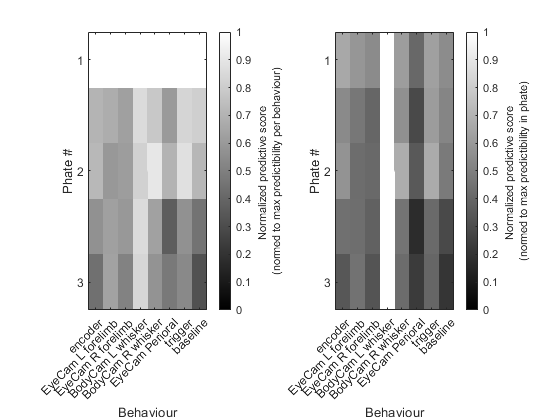

xticks(1:numel(behaviours));xticklabels(cellfun(@(x) strrep(x,'_',' '), behaviours, 'uni', false));xtickangle(45); hold on; xlabel('Behaviour');
yticks(1:2:18);hold on;yticklabels(cellfun(@(x) num2str(x), num2cell(1:N_phates), 'uni', false)); ylabel('Phate #');


% %to study combos of phate groups (e.g. phate 1-3 up/up/up, phate 1-3 down/down/down, phate 1 up/down, phate 2 up/down, phate 3 up/down)
% prepare_test_groups    % this generates lists of ROIs defined by up/down phate cutoff 
% for jj = 1:numel(test_groups)
%     test_groups{jj}
% 
% results_high_phate = {}; 
% for iter = 1:N_iter
%     results_high_phate{iter} = predict_behaviours(obj, false, 'linear', variable_type, behaviours, test_groups{jj}, 'optimize_hyper', true, 'rendering', rendering, 'optimization_method', 'manual', 'holdout', holdout, 'kfold',KFold);
% end
% bar_chart(results_high_phate, 'beh_type');title('Prediction on all behaviours, using modulation on High Phates')
% end

## On perisomatic ROIs

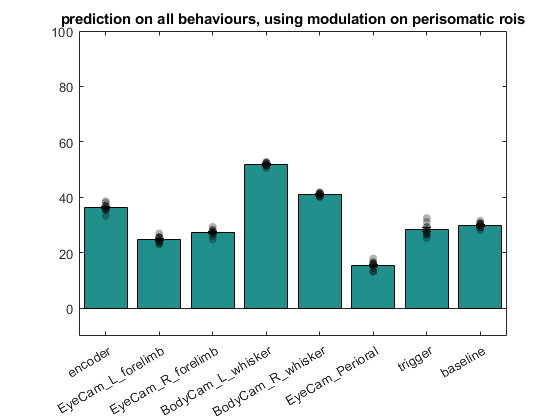

ROI_selection       = num2cell(obj.ref.indices.somatic_ROIs); % Get perisomatic ROIs (i.e 1st ROI of each branch emerging from the soma OR lowest ROIS of apical dendrite when no soma.
result_linear       = predict_behaviours(obj,use_classifier ,... % true or false
                                             method         ,... % 'linear' or 'svm'
                                             variable_type  ,... % 'peak_subtracted' or any other set of conditions / timepoints
                                             behaviours     ,... % Cell array of behaviours. add "_shuffled" to a behaviours name to shuffle timepoints
                                             ROI_selection  ,... % Cell array of ROI to use as predictor. One cell = one predictor. When multiple value per cell, values are avergaed. If passing a list, then all ROIs are used individually
                                             N_iter         ,... % N iterations
                                             false          ,... % if true, random groups are generated matching "ROI_selection" size
                                             'optimize_hyper', true     ,... % ML varargin ; if true, Lambda is optimized for each iteration
                                             'rendering', rendering     ,... % If 0 no figure, if 1 summary plot is display per iteraton + averages, if 2, individual iteration data is displayed , if 3 hyperparameter optimization plot are displayed.
                                             'optimization_method', 'manual',... % "manual" or "native". Native uses MATLAB baysian search parameter optimization for Lambda. Native generate a search grid and find Lambda with the best prediction score.. 
                                             'holdout', holdout         ,... % percentage of data held out for final testing. If 0, we use KFoldLoss with custom Pearson coeff to estimate the score
                                             'kfold', KFold             ,...
                                             'title', 'Prediction on all behaviours, using modulation on perisomatic ROIs'); % Bar chart title


%load_full_experiment('D:/SuperBackup Laptop TO DELETE/LaCie/Curated Data/2019-10-01/experiment_1', '', 2, -5, true, '', '', 'smoothing', [-1,1], 'rendering_mode', 'realistic','rendering',true,'ROIs',obj.ref.indices.somatic_ROIs);

# 4. Controls

## 4.1. Time Shuffling

% Using the entire dendritic tree on the encoder
ROI_selection       = [];
result_linear       = predict_behaviours(obj,use_classifier ,... % true or false
                                             method         ,... % 'linear' or 'svm'
                                             variable_type  ,... % 'peak_subtracted' or any other set of conditions / timepoints
                                             behaviours     ,... % Cell array of behaviours. add "_shuffled" to a behaviours name to shuffle timepoints
                                             ROI_selection  ,... % Cell array of ROI to use as predictor. One cell = one predictor. When multiple value per cell, values are avergaed. If passing a list, then all ROIs are used individually
                                             N_iter         ,... % N iterations
                                             false          ,... % if true, random groups are generated matching "ROI_selection" size
                                             'optimize_hyper', true     ,... % ML varargin ; if true, Lambda is optimized for each iteration
                                             'rendering', rendering     ,... % If 0 no figure, if 1 summary plot is display per iteraton + averages, if 2, individual iteration data is displayed , if 3 hyperparameter optimization plot are displayed.
                                             'optimization_method', 'manual',... % "manual" or "native". Native uses MATLAB baysian search parameter optimization for Lambda. Native generate a search grid and find Lambda with the best prediction score.. 
                                             'holdout', holdout         ,... % percentage of data held out for final testing. If 0, we use KFoldLoss with custom Pearson coeff to estimate the score
                                             'kfold', KFold             ,...
                                             'title', 'Prediction on all behaviours, using modulation on all ROIs, but Ca2+ events are shuffled',... % Bar chart title
                                             'shuffling','events'); 

## 4.2. Spatial Shuffling

% Using the entire dendritic tree on the encoder
ROI_selection       = [];
result_linear       = predict_behaviours(obj,use_classifier ,... % true or false
                                             method         ,... % 'linear' or 'svm'
                                             variable_type  ,... % 'peak_subtracted' or any other set of conditions / timepoints
                                             behaviours     ,... % Cell array of behaviours. add "_shuffled" to a behaviours name to shuffle timepoints
                                             ROI_selection  ,... % Cell array of ROI to use as predictor. One cell = one predictor. When multiple value per cell, values are avergaed. If passing a list, then all ROIs are used individually
                                             N_iter         ,... % N iterations
                                             false          ,... % if true, random groups are generated matching "ROI_selection" size
                                             'optimize_hyper', true     ,... % ML varargin ; if true, Lambda is optimized for each iteration
                                             'rendering', rendering     ,... % If 0 no figure, if 1 summary plot is display per iteraton + averages, if 2, individual iteration data is displayed , if 3 hyperparameter optimization plot are displayed.
                                             'optimization_method', 'manual',... % "manual" or "native". Native uses MATLAB baysian search parameter optimization for Lambda. Native generate a search grid and find Lambda with the best prediction score.. 
                                             'holdout', holdout         ,... % percentage of data held out for final testing. If 0, we use KFoldLoss with custom Pearson coeff to estimate the score
                                             'kfold', KFold             ,...
                                             'title', 'Prediction on all behaviours, using modulation on all ROIs, but Ca2+ events are shuffled',... % Bar chart title
                                             'shuffling','ROIs'); 


## 4.3. Trial Shuffling

% Using the entire dendritic tree on the baseline and encoder
trial_shuff_results = {}; 
shuffled_beh  = strcat(behaviours, '_shuffle');
shuffled_beh = reshape([behaviours; shuffled_beh],[],1)';
%shuffled_beh  = {'encoder','encoder_shuffle','EyeCam_L_forelimb','EyeCam_L_forelimb_shuffle','EyeCam_R_forelimb','EyeCam_R_forelimb_shuffle','BodyCam_L_whisker','BodyCam_L_whisker_shuffle','BodyCam_R_whisker','BodyCam_R_whisker_shuffle','EyeCam_Perioral','EyeCam_Perioral_shuffle','trigger','trigger_shuffle','baseline','baseline_shuffle'};
%shuffled_beh  = {'baseline','baseline_shuffle','encoder'}

%variable_type = 1:100:15000 % mimics the slow baseline drift measurement

% need to convert the time points t into amplitudes for valid ROIs, then
% feed this to variable_type
% below is just a first approx/ball park estimate:
% 
% tt = find(obj.get_tp_for_condition('peaks'))
% num_ev = numel(vertcat(obj.event.peak_time{:})); %could use this or several other of the obj.event outputs to get # of events
% rand_timepoints = sort(tt(randi(numel(tt),1,num_ev)))

result_linear       = predict_behaviours(obj,use_classifier ,... % true or false
                                             method         ,... % 'linear' or 'svm'
                                             variable_type  ,... % 'peak_subtracted' or any other set of conditions / timepoints
                                             shuffled_beh   ,... % Cell array of behaviours. add "_shuffled" to a behaviours name to shuffle timepoints
                                             ROI_selection  ,... % Cell array of ROI to use as predictor. One cell = one predictor. When multiple value per cell, values are avergaed. If passing a list, then all ROIs are used individually
                                             N_iter         ,... % N iterations
                                             false          ,... % if true, random groups are generated matching "ROI_selection" size
                                             'optimize_hyper', true     ,... % ML varargin ; if true, Lambda is optimized for each iteration
                                             'rendering', rendering     ,... % If 0 no figure, if 1 summary plot is display per iteraton + averages, if 2, individual iteration data is displayed , if 3 hyperparameter optimization plot are displayed.
                                             'optimization_method', 'manual',... % "manual" or "native". Native uses MATLAB baysian search parameter optimization for Lambda. Native generate a search grid and find Lambda with the best prediction score.. 
                                             'holdout', holdout         ,... % percentage of data held out for final testing. If 0, we use KFoldLoss with custom Pearson coeff to estimate the score
                                             'kfold', KFold             ,...
                                             'title', 'Prediction selected behaviours with and without shuffling, using modulation on all ROIs') % Bar chart title


% figure();plot(obj.rescaled_traces(:,77));hold on;scatter(variable_type, obj.rescaled_traces(variable_type,77),'r','filled')


## 4.4 ROI Groups Shuffling

## On randomized groups of ROIs

for condition = {'highest_phate', 'strong_phate', 'clusters', 'all'}
    switch condition{1}
        case 'highest_phate'
            N_phates        = 3;    % N dimensions
            cutoff          = 0;    % 0 is just min and max
            bidirectional   = true; % Postive AND negative magnitudes
            ROI_selection   = get_high_phate_ROIs(obj, N_phates, cutoff, bidirectional);      
        case 'strong_phate'
            N_phates        = 3;    % N dimensions
            cutoff          = 5;    % 0 is just min and max
            bidirectional   = true; % Postive AND negative magnitudes
            ROI_selection   = get_high_phate_ROIs(obj, N_phates, cutoff, bidirectional); 
        case 'clusters'
            obj.cluster_factors('dbscan',-5);
            ROI_selection   = obj.dimensionality.clust_groups;        
        case 'all'
            ROI_selection   = [];        
    end

    result_linear       = predict_behaviours(obj,use_classifier ,... % true or false
                                                 method         ,... % 'linear' or 'svm'
                                                 variable_type  ,... % 'peak_subtracted' or any other set of conditions / timepoints
                                                 behaviours     ,... % Cell array of behaviours. add "_shuffled" to a behaviours name to shuffle timepoints
                                                 ROI_selection  ,... % Cell array of ROI to use as predictor. One cell = one predictor. When multiple value per cell, values are avergaed. If passing a list, then all ROIs are used individually
                                                 N_iter         ,... % N iterations
                                                 true           ,... % if true, random groups are generated matching "ROI_selection" size
                                                 'optimize_hyper', true     ,... % ML varargin ; if true, Lambda is optimized for each iteration
                                                 'rendering', rendering     ,... % If 0 no figure, if 1 summary plot is display per iteraton + averages, if 2, individual iteration data is displayed , if 3 hyperparameter optimization plot are displayed.
                                                 'optimization_method', 'manual',... % "manual" or "native". Native uses MATLAB baysian search parameter optimization for Lambda. Native generate a search grid and find Lambda with the best prediction score.. 
                                                 'holdout', holdout         ,... % percentage of data held out for final testing. If 0, we use KFoldLoss with custom Pearson coeff to estimate the score
                                                 'kfold', KFold             ,...
                                                 'title', ['Prediction on all behaviours, using modulation on randomized ',condition{1},' ROIs']); % Bar chart title
end

# 5. Introducing Time Lag

%% Extract behaours first to prevent doing it every time inside the for-loop
extracted_beh   = prepare_behaviour_data(obj, behaviours);

%% Identify relevant timpoints
events_tp       = find(obj.get_tp_for_condition('peaks'));

%% Get lags
sr              = 1/nanmedian(obj.timescale.sr);
ROI_selection   = [];
R               = {};
%lag_list        = [fliplr(logspace(log10(0.1),log10(20),15))*-1,0, logspace(log10(0.1),log10(20),15)];
% lag_list      = [round(linspace(-10,0.1,15)),0, round(linspace(0.1,10,15))];
% lag_list      = [-200,-100,-50,-10,-5,-2,-1,-0.5,-0.2,-0.1,0,0.1,0.2,0.5,1,2,5,10,50,100,200];
lag_list        = [(0:0.5:30)*-1, (0:0.5:30)];
lag_list        = unique(round(sort(lag_list) * sr))

lag_list =   -265  -261  -257  -252  -248  -243  -239  -234  -230  -226  -221  -217  -212  -208  -204  -199  -195  -190  -186  -181  -177  -173  -168  -164  -159  -155  -150  -146  -142  -137  -133  -128  -124  -119  -115  -111  -106  -102   -97   -93   -88   -84   -80   -75   -71   -66   -62   -58   -53   -49



%% Run simulation for evry lag value
for lag_idx = 1:numel(lag_list) 
    lag_idx
    lag = lag_list(lag_idx);
    [result_linear,~,~, R{lag_idx}]       = predict_behaviours(obj,use_classifier ,... % true or false
                                                             method         ,... % 'linear' or 'svm'
                                                             ['peaks_subtracted','_lag',num2str(lag)]       ,... % 'peak_subtracted' or any other set of conditions / timepoints
                                                             extracted_beh  ,... % Cell array of behaviours. add "_shuffled" to a behaviours name to shuffle timepoints. Use prepare_behaviour_data(obj, behaviours) before predcit_behaviours if you call the function several times 
                                                             ROI_selection  ,... % Cell array of ROI to use as predictor. One cell = one predictor. When multiple value per cell, values are avergaed. If passing a list, then all ROIs are used individually
                                                             1         ,... % N iterations
                                                             false          ,... % if true, random groups are generated matching "ROI_selection" size
                                                             'optimize_hyper', true     ,... % ML varargin ; if true, Lambda is optimized for each iteration
                                                             'rendering', false     ,... % If 0 no figure, if 1 summary plot is display per iteraton + averages, if 2, individual iteration data is displayed , if 3 hyperparameter optimization plot are displayed.
                                                             'optimization_method', 'manual',... % "manual" or "native". Native uses MATLAB baysian search parameter optimization for Lambda. Native generate a search grid and find Lambda with the best prediction score.. 
                                                             'holdout', holdout         ,... % percentage of data held out for final testing. If 0, we use KFoldLoss with custom Pearson coeff to estimate the score
                                                             'kfold', KFold             ,...
                                                             'title', ['Prediction on all behaviours, using modulation on all ROIs with a lag of ',num2str(lag/10),' s']); % Bar chart title
end

lag_idx = 1

lag_idx = 2

lag_idx = 3

lag_idx = 4

lag_idx = 5

lag_idx = 6

lag_idx = 7

lag_idx = 8

lag_idx = 9

lag_idx = 10

lag_idx = 11

lag_idx = 12

lag_idx = 13

lag_idx = 14

lag_idx = 15

lag_idx = 16

lag_idx = 17

lag_idx = 18

lag_idx = 19

lag_idx = 20

lag_idx = 21

lag_idx = 22

lag_idx = 23

lag_idx = 24

lag_idx = 25

lag_idx = 26

lag_idx = 27

lag_idx = 28

lag_idx = 29

lag_idx = 30

lag_idx = 31

lag_idx = 32

lag_idx = 33

lag_idx = 34

lag_idx = 35

lag_idx = 36

lag_idx = 37

lag_idx = 38

lag_idx = 39

lag_idx = 40

lag_idx = 41

lag_idx = 42

lag_idx = 43

lag_idx = 44

lag_idx = 45

lag_idx = 46

lag_idx = 47

lag_idx = 48

lag_idx = 49

lag_idx = 50

lag_idx = 51

lag_idx = 52

lag_idx = 53

lag_idx = 54

lag_idx = 55

lag_idx = 56

lag_idx = 57

lag_idx = 58

lag_idx = 59

lag_idx = 60

lag_idx = 61

lag_idx = 62

lag_idx = 63

lag_idx = 64

lag_idx = 65

lag_idx = 66

lag_idx = 67

lag_idx = 68

lag_idx = 69

lag_idx = 70

lag_idx = 71

lag_idx = 72

lag_idx = 73

lag_idx = 74

lag_idx = 75

lag_idx = 76

lag_idx = 77

lag_idx = 78

lag_idx = 79

lag_idx = 80

lag_idx = 81

lag_idx = 82

lag_idx = 83

lag_idx = 84

lag_idx = 85

lag_idx = 86

lag_idx = 87

lag_idx = 88

lag_idx = 89

lag_idx = 90

lag_idx = 91

lag_idx = 92

lag_idx = 93

lag_idx = 94

lag_idx = 95

lag_idx = 96

lag_idx = 97

lag_idx = 98

lag_idx = 99

lag_idx = 100

lag_idx = 101

lag_idx = 102

lag_idx = 103

lag_idx = 104

lag_idx = 105

lag_idx = 106

lag_idx = 107

lag_idx = 108

lag_idx = 109

lag_idx = 110

lag_idx = 111

lag_idx = 112

lag_idx = 113

lag_idx = 114

lag_idx = 115

lag_idx = 116

lag_idx = 117

lag_idx = 118

lag_idx = 119

lag_idx = 120

lag_idx = 121

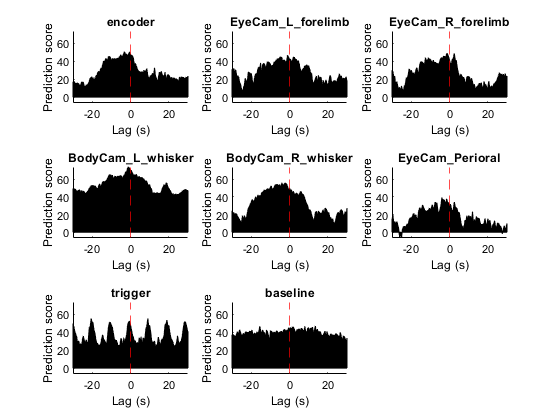


%% Plot lag results
a = cell2mat(R);x = lag_list/sr;
figure();tiledlayout('flow');
for beh = 1:numel(behaviours)
    axes(beh) = nexttile    ;  
    patch([x,fliplr(x)], [a(beh, :), zeros(size(a(beh, :)))], 'k');
    title(strrep(behaviours{beh},'_','\_'));xlabel('Lag (s)');ylabel('Prediction score');
    xline(0,'r--');
end
linkaxes(axes, 'xy')

# 6. Focusing on specific epochs

extracted_beh   = prepare_behaviour_data(obj, behaviours);

events_tp       = find(obj.get_tp_for_condition('peaks'));
sr              = 1/nanmedian(obj.timescale.sr);
ROI_selection   = [];
R               = {};

airpuff         = cellfun(@(x) any(contains(x, 'puff','IgnoreCase',true)), obj.logs); % puff, free, whisker
ok              = true(size(obj.t));
starts          = cumsum([1, obj.timescale.tp])
for trial = 1:numel(airpuff)
    if airpuff(trial)
        ok(starts(trial):(starts(trial+1)-1)) = false;
    end    
end
ok = ~ok;

%lag_list        = [fliplr(logspace(log10(0.1),log10(20),15))*-1,0, logspace(log10(0.1),log10(20),15)];
lag_list        = unique([[0:0.1:1,1:10,10:5:30]*-1, [0:0.1:1,1:10,10:5:30]])
% lag_list        = [fliplr(linspace(1,30,30))*-1,0, linspace(1,30,30)];

lag_list        = unique(round(lag_list * sr))
% beh_sub         = {'EyeCam_Perioral','BodyCam_L_whisker'}; % warning : You cannot test trigger by filtering aout all triggers


tic
for lag = 1:numel(lag_list)
    
    [result_linear,~,~, R{lag}]       = predict_behaviours(obj,use_classifier ,... % true or false
                                                             method         ,... % 'linear' or 'svm'
                                                             {['peaks_subtracted','_lag',num2str(lag_list(lag))], ok}       ,... % 'peak_subtracted' or any other set of conditions / timepoints
                                                             extracted_beh, ...%,'encoder','BodyCam_L_whisker'}     ,... % Cell array of behaviours. add "_shuffled" to a behaviours name to shuffle timepoints
                                                             ROI_selection  ,... % Cell array of ROI to use as predictor. One cell = one predictor. When multiple value per cell, values are avergaed. If passing a list, then all ROIs are used individually
                                                             1              ,... % N iterations
                                                             false          ,... % if true, random groups are generated matching "ROI_selection" size
                                                             'optimize_hyper', true     ,... % ML varargin ; if true, Lambda is optimized for each iteration
                                                             'rendering', false     ,... % If 0 no figure, if 1 summary plot is display per iteraton + averages, if 2, individual iteration data is displayed , if 3 hyperparameter optimization plot are displayed.
                                                             'optimization_method', 'manual',... % "manual" or "native". Native uses MATLAB baysian search parameter optimization for Lambda. Native generate a search grid and find Lambda with the best prediction score.. 
                                                             'holdout', holdout         ,... % percentage of data held out for final testing. If 0, we use KFoldLoss with custom Pearson coeff to estimate the score
                                                             'kfold', KFold             ,...
                                                             'title', ['Prediction on all behaviours, using modulation on all ROIs with a lag of ',num2str(lag_list(lag)/10),' s']); % Bar chart title
 
    

    a = cell2mat(R);x = lag_list(1:lag)/sr;
    figure(1);clf();
    tiledlayout('flow');
    for beh = 1:numel(extracted_beh.original_behaviour_list)
        axes(beh) = nexttile    ;
        %plot(x, a(beh, :)','o-');
        patch([x,fliplr(x)], [a(beh, :), zeros(size(a(beh, :)))], 'k')
        title(strrep(extracted_beh.original_behaviour_list{beh},'_','\_'));xlabel('Lag (s)');ylabel('Prediction score');
        xline(0,'r--')
    end
    linkaxes(axes, 'xy')
    % figure();plot(x, a','o-');legend(behaviours);xlabel('Lag (s)');ylabel('Prediction score');xline(0)
        
end
toc


figure(2);clf();
tiledlayout('flow');
for beh = 1:size(extracted_beh.raw_behaviours, 1)
    axes(beh) = nexttile    ;
    title(strrep(extracted_beh.original_behaviour_list{beh},'_','\_'));hold on
    plot(linspace(min(x), max(x), max(lag_list)*2+1), xcorr(extracted_beh.raw_behaviours(beh,:),max(lag_list),'normalized')); hold on
    xlabel('Lag (s)');xline(0,'r--')
end
% 
% a = cell2mat(R);x = lag_list/sr;
% figure(1);clf();
% tiledlayout('flow');
% for beh = 1:numel(extracted_beh.original_behaviour_list)
%     axes(beh) = nexttile    
%     %plot(x, a(beh, :)','o-');
%     patch([x,fliplr(x)], [a(beh, :), zeros(size(a(beh, :)))], 'k')
%     title(strrep(extracted_beh.original_behaviour_list{beh},'_','\_'));xlabel('Lag (s)');ylabel('Prediction score');
%     xline(0,'r--')
% end
% linkaxes(axes, 'xy')
% % figure();plot(x, a','o-');legend(behaviours);xlabel('Lag (s)');ylabel('Prediction score');xline(0)

# 7. Beta Coefficents

## 7.1 Beta coef for single behaviour

% Run Prediction for a specific behaviour
% Note that you need to get the beta coefs for the entire tree, or it can
% be complicated to display
ROI_selection       = [];
result_linear       = predict_behaviours(obj,use_classifier ,... % true or false
                                             method         ,... % 'linear' or 'svm'
                                             variable_type  ,... % 'peak_subtracted' or any other set of conditions / timepoints
                                             {'encoder'}     ,... % Cell array of behaviours. add "_shuffled" to a behaviours name to shuffle timepoints
                                             ROI_selection  ,... % Cell array of ROI to use as predictor. One cell = one predictor. When multiple value per cell, values are avergaed. If passing a list, then all ROIs are used individually
                                             N_iter         ,... % N iterations
                                             false          ,... % if true, random groups are generated matching "ROI_selection" size
                                             'optimize_hyper', true     ,... % ML varargin ; if true, Lambda is optimized for each iteration
                                             'rendering', false     ,... % If 0 no figure, if 1 summary plot is display per iteraton + averages, if 2, individual iteration data is displayed , if 3 hyperparameter optimization plot are displayed.
                                             'optimization_method', 'manual',... % "manual" or "native". Native uses MATLAB baysian search parameter optimization for Lambda. Native generate a search grid and find Lambda with the best prediction score.. 
                                             'holdout', holdout         ,... % percentage of data held out for final testing. If 0, we use KFoldLoss with custom Pearson coeff to estimate the score
                                             'kfold', KFold             ,...
                                             'title', 'Prediction on all behaviours, using modulation on all ROIs'); % Bar chart title

all_scores = extract_ML_coefs(obj, result_linear, true, 'beta')



## 7.2 Display Beta coefs

% Run with deifferent lags, and display beta coef in an animation
extracted_beh   = prepare_behaviour_data(obj, 'trigger');

lag_list        = [fliplr(logspace(log10(0.1),log10(20),15))*-1,0, logspace(log10(0.1),log10(20),15)];
lag_list        = unique(round(lag_list * sr));
R               = {};

for lag_idx = 1:numel(lag_list) 
    lag_idx
    lag = lag_list(lag_idx);
    [result_linear,~,~, R{lag_idx}]       = predict_behaviours(obj,use_classifier ,... % true or false
                                                 method         ,... % 'linear' or 'svm'
                                                 ['peaks_subtracted','_lag',num2str(lag)],...
                                                 extracted_beh  ,... % Cell array of behaviours. add "_shuffled" to a behaviours name to shuffle timepoints
                                                 ROI_selection  ,... % Cell array of ROI to use as predictor. One cell = one predictor. When multiple value per cell, values are avergaed. If passing a list, then all ROIs are used individually
                                                 1              ,... % N iterations
                                                 false          ,... % if true, random groups are generated matching "ROI_selection" size
                                                 'optimize_hyper', true     ,... % ML varargin ; if true, Lambda is optimized for each iteration
                                                 'rendering', false     ,... % If 0 no figure, if 1 summary plot is display per iteraton + averages, if 2, individual iteration data is displayed , if 3 hyperparameter optimization plot are displayed.
                                                 'optimization_method', 'manual',... % "manual" or "native". Native uses MATLAB baysian search parameter optimization for Lambda. Native generate a search grid and find Lambda with the best prediction score.. 
                                                 'holdout', holdout         ,... % percentage of data held out for final testing. If 0, we use KFoldLoss with custom Pearson coeff to estimate the score
                                                 'kfold', KFold             ,...
                                                 'title', 'Prediction on all behaviours, using modulation on all ROIs'); % Bar chart title

    all_scores{lag_idx} = extract_ML_coefs(obj, result_linear, false, 'beta');
end

%% Note : small video of the beta coefs + predictive score for a giver behaviour, to capture with OBS 
values = cell2mat(cellfun(@(x) nanmean(x{1})', all_scores, 'UniformOutput', false))';
for lag_idx = 1:numel(lag_list) 
    figure(123); clf();
    ax1 = subplot(1,2,1);beh_idx = 1;
    obj.ref.plot_value_tree(values(lag_idx,:), cell2mat(result_linear{1}.used_ROIs),'',['encoder with lag = ',num2str(lag_list(lag_idx))],'',ax1);
%     pause(0.3)
    ax2 = subplot(1,2,2);cla();beh_idx = 1;
    a = cell2mat(R);x = lag_list/sr;
    patch([x,fliplr(x)], [a(beh_idx, :), zeros(size(a(beh_idx, :)))], 'k')
    title(strrep(extracted_beh.original_behaviour_list{beh_idx},'_',' '));xlabel('Lag (s)');ylabel('Prediction score');
    xline(x(lag_idx),'b-');
    xline(0,'r--');pause(0.1)
end
%obj.animate_experiment(values, '', cell2mat(result_linear{1}.used_ROIs))


for sm = [0,1,10]
    extracted_beh   = prepare_behaviour_data(obj, behaviours,true, sm);
    figure();clf();
    tiledlayout('flow');
    for beh = 1:size(extracted_beh.raw_behaviours, 1)
        axes(beh) = nexttile    ;
        title(strrep(extracted_beh.original_behaviour_list{beh},'_','\_'));hold on
        plot(linspace(min(x), max(x), max(lag_list)*2+1), xcorr(extracted_beh.raw_behaviours(beh,:),max(lag_list),'normalized')); hold on
        xlabel('Lag (s)');xline(0,'r--')
    end
end

for beh = behaviours
%beh = 'L_forelimb';
    raw_beh = get_behaviours(obj, beh{1}, false, true, true, false);
    raw_beh = raw_beh{1};
    test = cellfun(@(x) x.value, raw_beh, 'uni', false);
    test = vertcat(test{:});
    test(isnan(test)) = 0;
    figure();plot(xcorr(vertcat(test), 150));title(beh{1})
end

## Setp 1 identify a group of Phate discovered ROIs that have a strong specific tuning




Phate_nb = 5;
figure();title(['Phate # ',num2str(Phate_nb)])
plot(obj.t,nanmean(obj.rescaled_traces(:,groups{Phate_nb*2-1}),2) - obj.global_median_rescaled,'g'); hold on;
set(gcf, 'Color', 'w'); hold on;
plot(obj.t,nanmean(obj.rescaled_traces(:,groups{Phate_nb*2}),2) - obj.global_median_rescaled,'r'); hold on;
set(gcf, 'Color', 'w'); hold on;
[~,~,trig] = obj.get_behaviours('trigger'); hold on;
plot(obj.t,trig.value,'k','LineWidth',2);legend({'Positive Phate','Negative Phate'});
xlim([1100,1500]);
ylim([-10,20])

5. Control based on the baseline behaviour

- h-word

- test if Ca is dirtributed normally (it should be, almost)

% run some (n = 16) key controls (e.g. do ML fo all ROIs with peaks_subtracted, raw_peaks, raw, raw_queit, quiet_subtracted
% plus a few shuffles where most relevant)

v = obj.rescaled_traces(obj.get_tp_for_condition('peaks'), :);
figure();hist(v(:),100);title('distribution of rescaled events amplitude (all ROIs)')
figure();hist(reshape((v - obj.global_median_rescaled(obj.get_tp_for_condition('peaks'))),[],1),100);title('distribution of median subtracted rescaled events amplitude (all ROIs)')



% plot_prediction(out{1}.calcium, out{1}.bin_beh{1}, out{1}.peak_tp{1}, out{1}.train_range{1}, out{1}.prediction{1}, out{1}.full_beh{1} , out{1}.beh_type{1}, out{1}.score{1});
